# Intro and references

## Nanocompartments proteins and promoters

### ΔVP1

There is no Uniprot reference exactly for this protein, here is the similar wild type protein:

[P49302 (VP1_POVMP)](https://www.uniprot.org/uniprotkb/P49302/entry)

Promoter used:

Gal1

### VP2C-GFP

[P12908 (VP2_POVMC)](https://www.uniprot.org/uniprotkb/P12908/entry)

Promoter used:

Gal10

# Model: constitutive gene expression

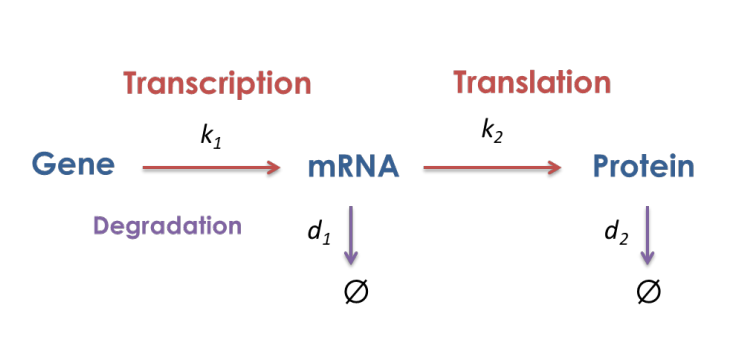

## Define model constants

p.CN = 17; % initial number of plasmids
% TODO: how to +- calculate it from the lab protocol?
p.d1 = log(2)/3; % mRNA degradation rate
p.d2 = 0.02; % degradation rate
p.k2 = 8.23; % translation rate
p.k1 = 1.19; % transcription rate

## Define simulation parameters

tfin = 60*5;
step = 0.1;
tspan = 0:step:tfin-step;

## Run the simulation

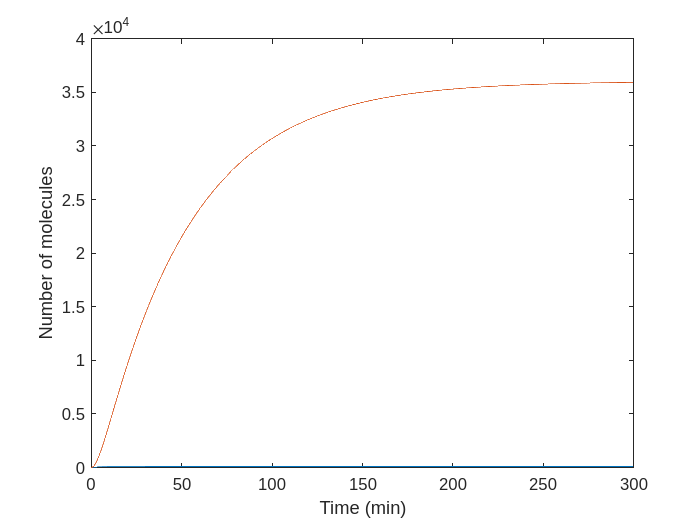

opti = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);

Init = [0 0];

[t0, x0] = ode23t(@(t, x) model_const(t, x, p), tspan, Init, opti);

plot(t0, x0);
xlabel('Time (min)');
ylabel('Number of molecules')

# Discussion

Actually, all this modeling doesn't make any sence, because I couldn't find all the needed constants.

Here is my suggestion what we can do - "reverse engineer" it, using GFP(t) graph frome the article:

- Adjust the constants so that the peak is on 5 mins and derivative of the curve is the same

- Estimate the initial number of plasmids (read the lab protocol)

- Get the number of molecules, calculate the concentration

function [dxdt] = model_const(t, x, p)
    dxdt(1,1) = p.CN*p.k1-p.d1*x(1);
    dxdt(2,1) = p.k2*x(1)-p.d2*x(2);
end